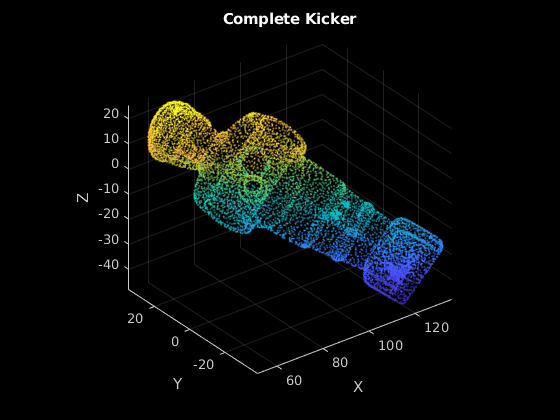


clear all; clf; clc;

points = readtable("Kicker_complete.xlsx");
points = points{:,1:3};

pcshow(points,"MarkerSize",7,"VerticalAxis","Z")
title("Complete Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")



points_aligned = rotatePointCloudAlongZ(points, "x", "",0);
x = points_aligned(:,1);
y = points_aligned(:,2);
z = points_aligned(:,3);

% h = get(gcf, "Children");
XLim = max(x)

XLim = 18.2936

YLim = max(y)

YLim = 13.4333

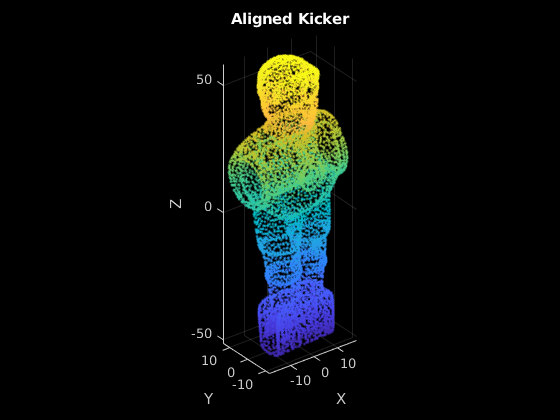

pcshow(points_aligned,"MarkerSize",13,"VerticalAxis","Z")
% set(h, 'Tag','left')
title("Aligned Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")
axh = gca; % use current axes
color = 'k'; % black, or [0 0 0]
linestyle = ':'; % dotted
line(get(axh,'XLim'), [0 0], 'Color', color, 'LineStyle', linestyle);
line([0 0], get(axh,'YLim'), 'Color', color, 'LineStyle', linestyle);

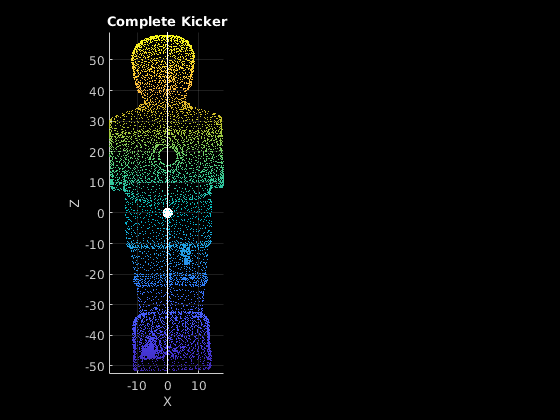

 
ax1 = subplot(1,2,1);
pcshow(points_aligned,"MarkerSize",7,"VerticalAxis","Z")
% set(h, 'Tag','left')
title("Complete Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")
hold(ax1, "on")

limz = [min(z)-1 min(z)-1 
        max(z)+1 max(z)+1];
limy = [min(y)-1 max(y)+1 
        min(y)-1 max(y)+1];
limx = [0 0 
        0 0];
% h = findobj('Tag','left');
% set(h,'NextPlot','add')
plot3(0, 0, 0,'o','color','w',"MarkerSize",7,'MarkerFaceColor',"white")
% h = findobj('Tag','left');
% set(h,'NextPlot','add')
surf(limx, limy, limz, "LineStyle","-", "FaceAlpha",0.55,"EdgeColor",[1,1,1] )

subplot(1,2,1)
view([0 0])

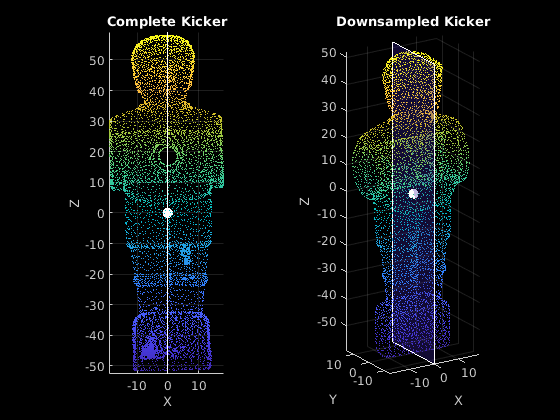


points = readtable("Kicker_complete.xlsx");
points = points{:,1:3};

points = pointCloud(points);

gridStep = 1;
points_downsampled = pcdownsample(points, "gridAverage", gridStep);
points_downsampled = points_downsampled.Location;

points_downsampled = rotatePointCloudAlongZ(points_downsampled, "x","",0);
x = points_downsampled(:,1);
y = points_downsampled(:,2);
z = points_downsampled(:,3);


% h = subplot(1,2,2);
% set(h, 'Tag','right')
ax2 = subplot(1,2,2);
pcshow(points_downsampled,"MarkerSize",7,"VerticalAxis","Z")
title("Downsampled Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")
hold(ax2, "on")

limz = [min(z)-1 min(z)-1 
        max(z)+1 max(z)+1];
limy = [min(y)-1 max(y)+1 
        min(y)-1 max(y)+1];
limx = [0 0 
        0 0];

plot3(0, 0, 0,'o','color','w',"MarkerSize",7,'MarkerFaceColor',"white")

surf(limx, limy, limz, "LineStyle","-", "FaceAlpha",0.3,"EdgeColor",[1,1,1] )
hold(ax1, "off")
hold(ax2, "off")



subplot(1,2,1)
view([0 0])
subplot(1,2,2)
view([0 0])


csvwrite("Kicker_complete_Output.xlsx", points_downsampled);


